Homework 1

% Question 2
clear all

Sigma = [1, 1, 0,
         1, 1, 0,
         0, 0, 2];
[V, D] = eig(Sigma)

V =    -0.7071    0.7071         0
    0.7071    0.7071         0
         0         0    1.0000


D =      0     0     0
     0     2     0
     0     0     2



% A = PDPt

A = V * D * V.'

A =     1.0000    1.0000         0
    1.0000    1.0000         0
         0         0    2.0000


Question 4

Displacement = [0.15, 0.24,
                0.0, -0.15];
% For value in position (i, j)

% Stress(ij) = 1/2(Displacement(i,j) - Displacement(j, i)

Stress = [0.0, 0.12,
          0.12, 0];

% Rotation(ij) = 1/2(Displacement(i, j) - Displacement(j, i)
Rotation = [0.15,0.12,
            -0.12,-0.15];

Question 5

% 5a

radius = 200; % Meters
fill_rate = 400000; % Cubic Meters Per Day

depth_per_day = fill_rate / (pi * radius.^2) % Meters Per Day

depth_per_day = 3.1831

depth_per_hour = depth_per_day / 24 % Meters Per Hour

depth_per_hour = 0.1326

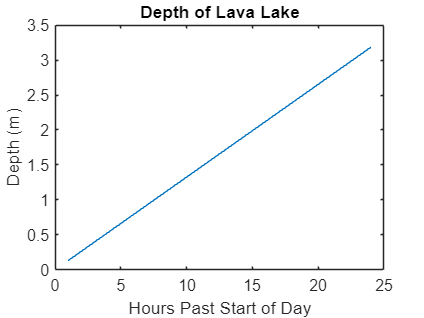

depth_initial = 0; % Meters

figure(1)
time = [1:1:24];
depth = (depth_per_hour * time) + depth_initial;

plot(time, depth)
title('Depth of Lava Lake')
subtitle('Given Initial Depth of 0')
xlabel('Hours Past Start of Day')
ylabel('Depth (m)')

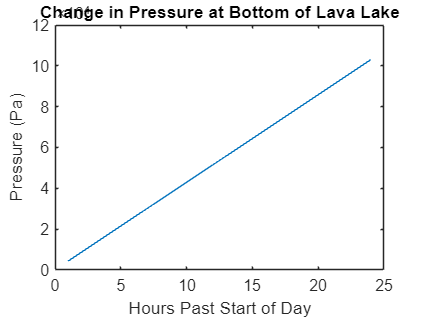


% 5b
density = 3300; % kg/m^3
gravity = 9.81; % m/s
pressure = density * gravity * depth; % Pascals

figure(2)
plot(time, pressure)
title('Change in Pressure at Bottom of Lava Lake')
subtitle('Given Initial Depth of 0')
xlabel('Hours Past Start of Day')
ylabel('Pressure (Pa)')